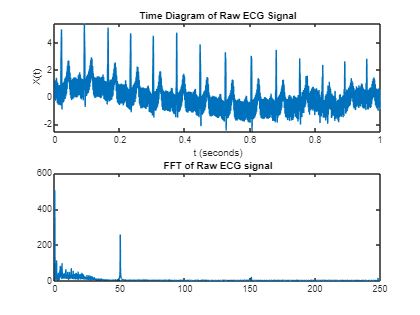

%Initialization
Fsample = 500; %(From Database)
T = 1/Fsample;
L = 20;

%ECG Generation
X = readmatrix("original_ecg.csv"); %from ECG Database folder
n = length(X);
t = (0:T:10-T)*(Fsample/n);

ECG = normalize(X);
XX = fft(X);
f = (0:n-1)*(Fsample/n);
L = 1:floor(n/2); %plots first half of freqs

figure;
subplot(211); plot(t,ECG); title('Time Diagram of Raw ECG Signal'); xlabel('t (seconds)'); ylabel('X(t)')
subplot(212); plot(f(L),abs(XX(L))); title('FFT of Raw ECG signal');

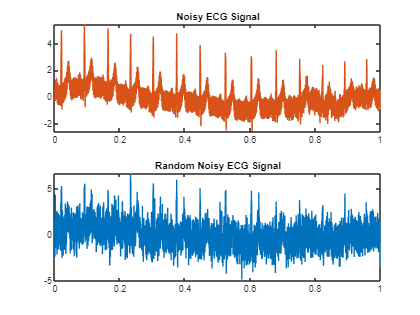

%Noise Generation and Application
Flownoise= 5; 
Fmednoise =60; 
Fhighnoise = 200; 
Anoise = 0.01;

LowNoise = Anoise*sin(2*pi*Flownoise.*t);
MedNoise = Anoise*sin(2*pi*Fmednoise.*t);
HighNoise = Anoise*sin(2*pi*Fhighnoise.*t);
Noise = LowNoise + MedNoise + HighNoise;
RandomNoise = randn(size(ECG));

ECGNoise = ECG+Noise;
ECGRandom = ECG+RandomNoise;

%Fast Fourier Transform
ECGNoiseFFT = fft(ECGNoise);
ECGRandomFFT = fft(ECGRandom);

figure;
subplot(211); plot(t,ECGNoise); title('Noisy ECG Signal');
subplot(212); plot(t,ECGRandom); title('Random Noisy ECG Signal');

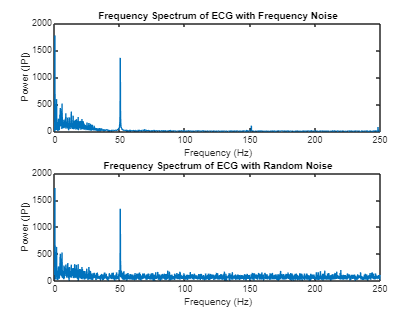


figure;
subplot(211); plot(f(L),abs(ECGNoiseFFT(L))); xlabel('Frequency (Hz)'); ylabel('Power (|P|)'); title('Frequency Spectrum of ECG with Frequency Noise');
subplot(212); plot(f(L),abs(ECGRandomFFT(L))); xlabel('Frequency (Hz)'); ylabel('Power (|P|)'); title('Frequency Spectrum of ECG with Random Noise');

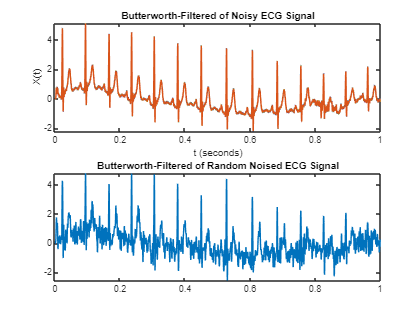

%Filter Creation and Application (Create Filters Here)
Fcutoff = 40;
Fcfnorm = 2*Fcutoff/Fsample;

%Butterworth
[b1,a1] = butter(12,Fcfnorm,'low');
ECGButterNoise=filter(b1,a1,ECGNoise);
ECGButterRandom=filter(b1,a1,ECGRandom);
FFTButterNoise = fft(ECGButterNoise);
FFTButterRandom = fft(ECGButterRandom);


figure;
subplot(211); plot(t,ECGButterNoise); xlabel('t (seconds)'); ylabel('X(t)'); title('Butterworth-Filtered of Noisy ECG Signal');
subplot(212); plot(t,ECGButterRandom); title('Butterworth-Filtered of Random Noised ECG Signal');

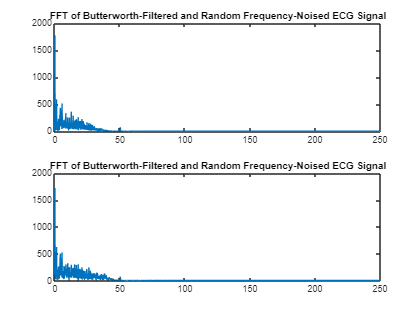



figure;
subplot(211); plot(f(L),abs(FFTButterNoise(L))); title('FFT of Butterworth-Filtered and Random Frequency-Noised ECG Signal');
subplot(212); plot(f(L),abs(FFTButterRandom(L))); title('FFT of Butterworth-Filtered and Random Frequency-Noised ECG Signal');

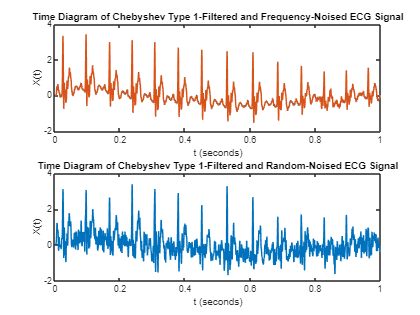

%Chebeyshev Type 1
[b2,a2] = cheby1(12,5,Fcfnorm,'low');
ECGCheby1Noise=filter(b2,a2,ECGNoise);
ECGCheby1Random=filter(b2,a2,ECGRandom);
FFTCheby1Noise = fft(ECGCheby1Noise);
FFTChbey1Random = fft(ECGCheby1Random);

figure;
subplot(211); plot(t,ECGCheby1Noise); title('Time Diagram of Chebyshev Type 1-Filtered and Frequency-Noised ECG Signal'); xlabel('t (seconds)'); ylabel('X(t)');
subplot(212); plot(t,ECGCheby1Random); title('Time Diagram of Chebyshev Type 1-Filtered and Random-Noised ECG Signal'); xlabel('t (seconds)'); ylabel('X(t)');

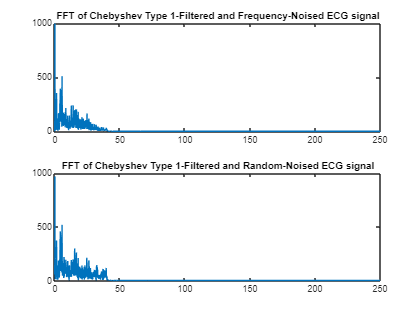

figure;
subplot(211); plot(f(L),abs(FFTCheby1Noise(L))); title('FFT of Chebyshev Type 1-Filtered and Frequency-Noised ECG signal')
subplot(212); plot(f(L),abs(FFTChbey1Random(L))); title('FFT of Chebyshev Type 1-Filtered and Random-Noised ECG signal')

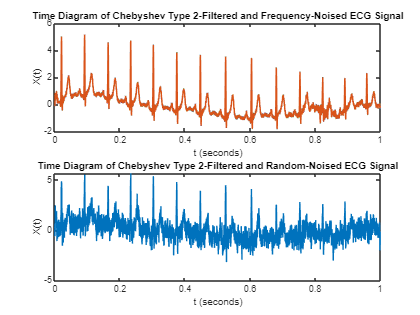


%Chebeyshev Type 2
[b3,a3] = cheby2(12,5,Fcfnorm,'low');
ECGCheby2Noise=filter(b3,a3,ECGNoise);
ECGCheby2Random=filter(b3,a3,ECGRandom);
FFTCheby2Noise = fft(ECGCheby2Noise);
FFTChbey2Random = fft(ECGCheby2Random);

figure;
subplot(211); plot(t,ECGCheby2Noise); title('Time Diagram of Chebyshev Type 2-Filtered and Frequency-Noised ECG Signal'); xlabel('t (seconds)'); ylabel('X(t)');
subplot(212); plot(t,ECGCheby2Random); title('Time Diagram of Chebyshev Type 2-Filtered and Random-Noised ECG Signal'); xlabel('t (seconds)'); ylabel('X(t)');

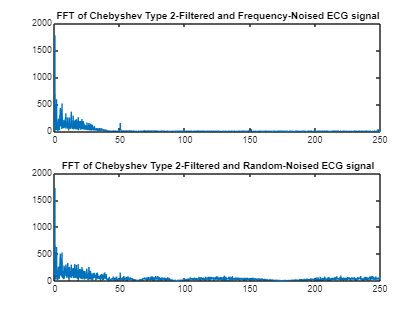


figure;
subplot(211); plot(f(L),abs(FFTCheby2Noise(L))); title('FFT of Chebyshev Type 2-Filtered and Frequency-Noised ECG signal')
subplot(212); plot(f(L),abs(FFTChbey2Random(L))); title('FFT of Chebyshev Type 2-Filtered and Random-Noised ECG signal')

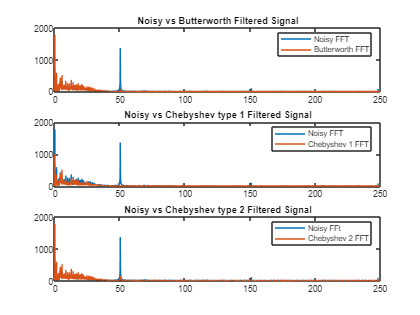

%signal analysis (hold on and off)

%from noisy signal
figure;
subplot(311); plot(f(L),abs(ECGNoiseFFT(L))); hold on; plot(f(L),abs(FFTButterNoise(L))); hold off; title('Noisy vs Butterworth Filtered Signal'); legend('Noisy FFT','Butterworth FFT');
subplot(312); plot(f(L),abs(ECGNoiseFFT(L))); hold on; plot(f(L),abs(FFTCheby1Noise(L))); hold off; title('Noisy vs Chebyshev type 1 Filtered Signal'); legend('Noisy FFT','Chebyshev 1 FFT');
subplot(313); plot(f(L),abs(ECGNoiseFFT(L))); hold on; plot(f(L),abs(FFTCheby2Noise(L))); hold off; title('Noisy vs Chebyshev type 2 Filtered Signal'); legend('Noisy FFt','Chebyshev 2 FFT');

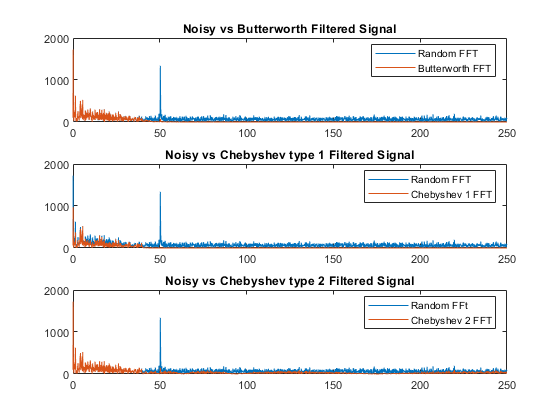

%from random signal
figure;
subplot(311); plot(f(L),abs(ECGRandomFFT(L))); hold on; plot(f(L),abs(FFTButterRandom(L))); hold off; title('Noisy vs Butterworth Filtered Signal'); legend('Random FFT','Butterworth FFT');
subplot(312); plot(f(L),abs(ECGRandomFFT(L))); hold on; plot(f(L),abs(FFTChbey1Random(L))); hold off; title('Noisy vs Chebyshev type 1 Filtered Signal'); legend('Random FFT','Chebyshev 1 FFT');
subplot(313); plot(f(L),abs(ECGRandomFFT(L))); hold on; plot(f(L),abs(FFTChbey2Random(L))); hold off; title('Noisy vs Chebyshev type 2 Filtered Signal'); legend('Random FFt','Chebyshev 2 FFT');